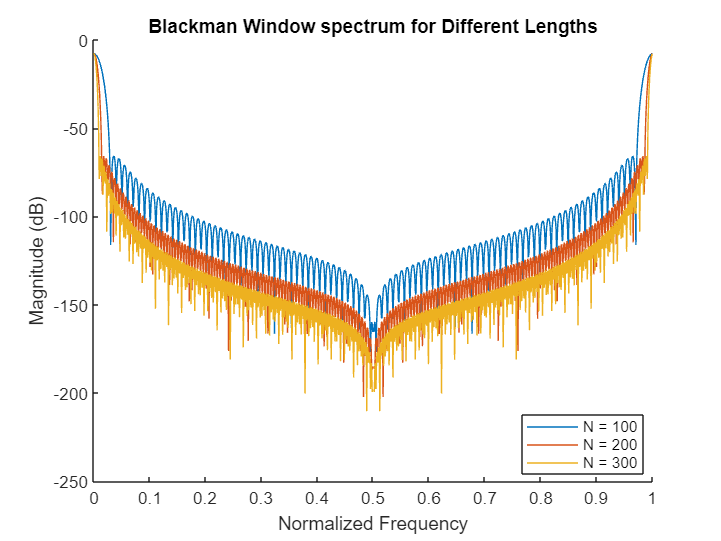

%Q1
N_values = [100, 200, 300];
DFT_Size = 1024;
frequencies = linspace(0, 1, DFT_Size);


figure;

hold on;

% alpha = 2, hence blackmann windowing is used
for i = 1:length(N_values)
    N = N_values(i);
    
    window = blackman(N);
    
    % Zero pad the window to match the DFT size
    window_padded = [window; zeros(DFT_Size - N, 1)];
    
    % DFT
    window_spectrum = fft(window_padded);
    
    
    window_spectrum_magnitude = abs(window_spectrum) / N;
    
    
    plot(frequencies, 20 * log10(window_spectrum_magnitude), 'DisplayName', ['N = ', num2str(N)]);
end

hold off;

title('Blackman Window spectrum for Different Lengths');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
xlim([0, 1]);
legend('Location','best');

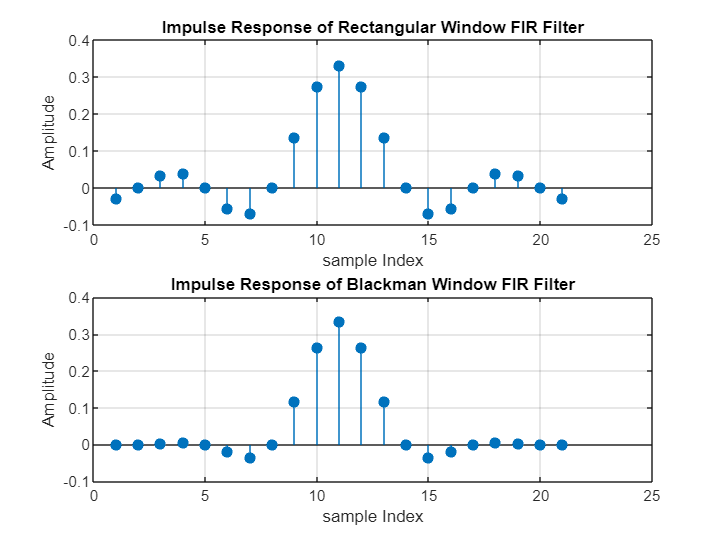

%Q2
alpha = 2;
wc = pi / (alpha + 1); 
N = 21;
h_blackman = fir1(N - 1, wc / pi, 'low', blackman(N));
h_rectangular = fir1(N - 1, wc / pi, 'low', rectwin(N));

% Plot the impulse response of the two filters
figure;
subplot(2, 1, 1);
stem(h_rectangular, 'filled');
title('Impulse Response of Rectangular Window FIR Filter');
xlabel('sample Index');
ylabel('Amplitude');
grid on;

subplot(2, 1, 2);
stem(h_blackman, 'filled');
title('Impulse Response of Blackman Window FIR Filter');
xlabel('sample Index');
ylabel('Amplitude');
grid on;

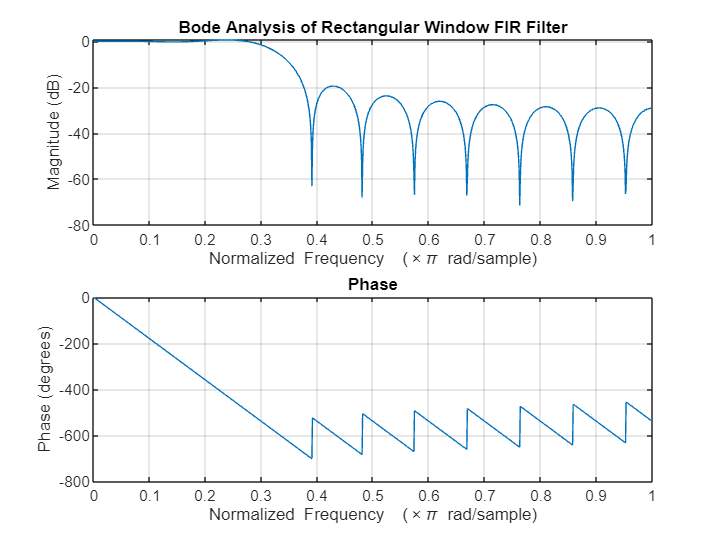


% Perform Bode analysis on the two filters
figure;
freqz(h_rectangular, 1, 1024); % Bode analysis for Rectangular window filter
title('Bode Analysis of Rectangular Window FIR Filter');

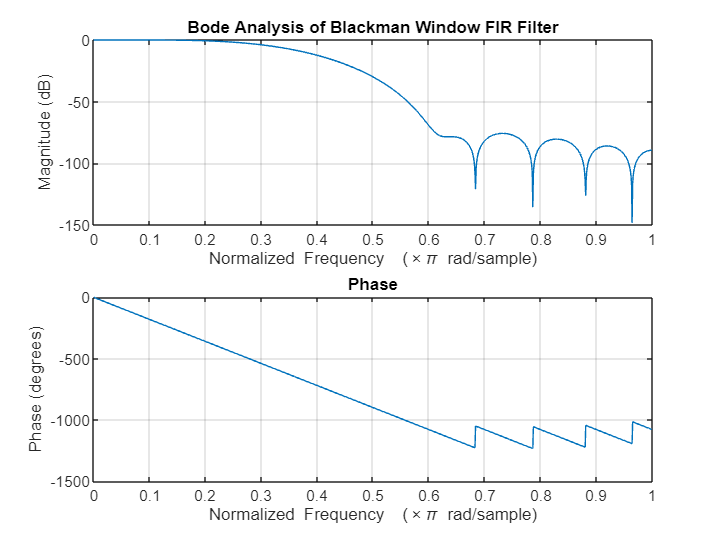


figure;
freqz(h_blackman, 1, 1024); % Bode analysis for Hanning window filter
title('Bode Analysis of Blackman Window FIR Filter');

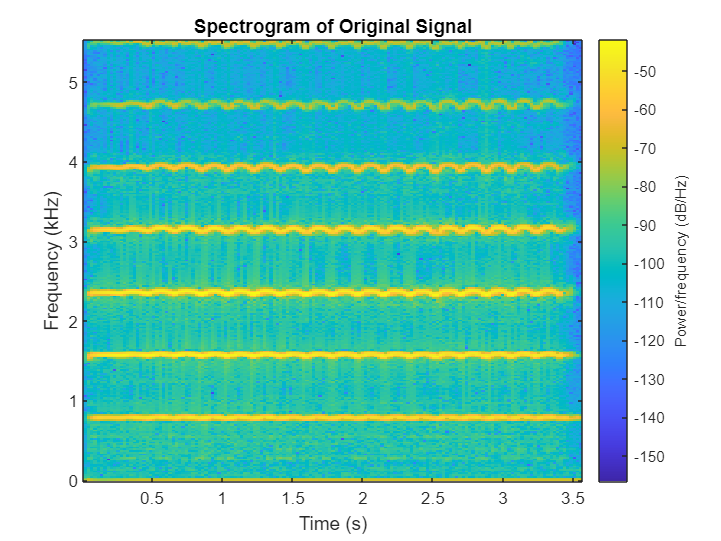

% Q3
% Load the audio file
[x, Fs] = audioread('instru2.wav');

% Plot the spectrogram of the original signal
figure;
spectrogram(x, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Original Signal');

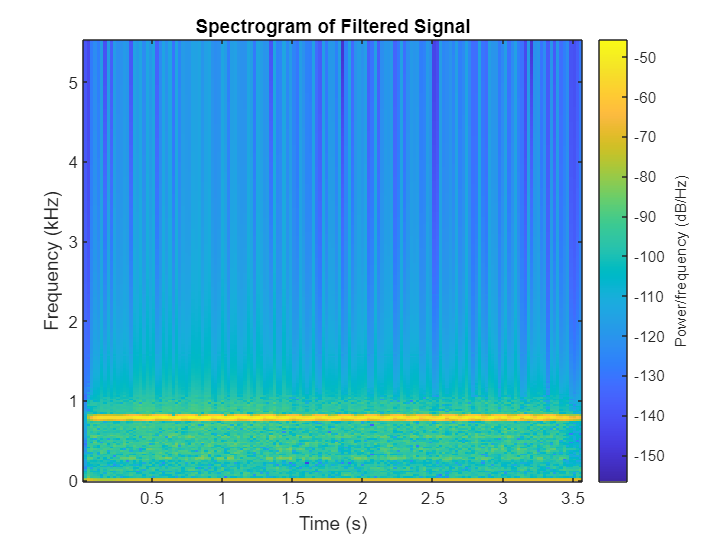


% Design a digital FIR filter (e.g., using a Blackman window)
filter_order = 100; % Adjust the order as needed
cutoff_freq = 1000; % Adjust the cutoff frequency as needed
desired_response = [1, zeros(1, filter_order - 1)]; % Desired frequency response

% Design the filter
b = fir1(filter_order, cutoff_freq / (Fs/2), 'low', blackman(filter_order+1));
% Apply the filter to the signal
filtered_signal = filter(b, 1, x);

% Write the filtered signal to a .wav file
audiowrite('filtered_instru2.wav', filtered_signal, Fs);

% Listen to the filtered audio
sound(filtered_signal, Fs);

% Plot the spectrogram of the filtered signal
figure;
spectrogram(filtered_signal, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Filtered Signal');